% Rocky_closed_loop_poles_23.m
%
% 1) Symbolically calculates closed loop transfer function of a disturbannce
% rejection PI control system for Rocky.
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this, the control constants can be found exactly
%
% 5) Plot impulse and step response to see closed-loop behavior.
%
% based on code by SG. last modified 2/25/23 CL
clear all;
close all;
syms s a b l g Kp Ki % define symbolic variables
Hvtheta = -s/l/(s^2-g/l); % TF from velocity to angle of pendulum
K = Kp + Ki/s; % TF of the PI angle controller
M = a*b/(s+a) % TF of motor (1st order model)

$$M = \frac{a\,b}{a+s}$$

% M = 1; % TF without motor
%
%
% closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K) % use this for no motor feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)}-1}$$

% pretty(simplify(Hcloop)) % to display the total transfer function

% Substitute parameters and solve
% system parameters
g = 9.81;
w_n = 4.88;

l = g/(w_n^2)%22*2.54/100 %effective length

l = 0.4119

a = 1/0.0459; %nominal motor parameters
b = 0.00323; %nominal motor parameters
Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{565592\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{3310875\,\left(s^{2}-\frac{14884}{625}\right)\,\left(s+\frac{10000}{459}\right)}+1}$$

% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc.
p1 = -0.2 + 0.492i % dominant pole pair

p1 = -0.2000 + 0.4920i

p2 = -0.2 - 0.492i % dominant pole pair

p2 = -0.2000 - 0.4920i

p3 = -10

p3 = -10

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

$$tgt\_char\_poly = \left(s+10\right)\,\left(s+\frac{1}{5}-\frac{123}{250}\,\mathrm{i}\right)\,\left(s+\frac{1}{5}+\frac{123}{250}\,\mathrm{i}\right)$$

npoly = 3

npoly = 3

% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = 981\,\left(459\,s+10000\right)\,\left(625\,s^{2}-14884\right)$$

$$d = 48075320\,\mathrm{Ki}-6701952636\,s+48075320\,\mathrm{Kp}\,s+6131250000\,s^{2}+281424375\,s^{3}-146012040000$$

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccc} 48075320\,\mathrm{Ki}-146012040000 & 48075320\,\mathrm{Kp}-6701952636 & 6131250000 & 281424375 \end{array}\right)$$

% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccc} \frac{565592\,\mathrm{Ki}}{3310875}-\frac{238144}{459} & \frac{565592\,\mathrm{Kp}}{3310875}-\frac{14884}{625} & \frac{10000}{459} & 1 \end{array}\right)$$

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccc} \frac{17629}{6250} & \frac{267629}{62500} & \frac{52}{5} & 1 \end{array}\right)$$

% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:npoly-1) == coeffs_tgt(1:npoly-1), Kp, Ki)

solutions = struct with fields:
    Kp: 46511940123/282796000
    Ki: 24066530631/7881200


% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 164.4717

Ki = double(solutions.Ki)

Ki = 3.0537e+03

% reorder coefficients for the check polynomial
for ii = 1:length(coeffs_denom)
chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end
closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), npoly )

$$closed\_loop\_poles = \left(\begin{array}{c} -21.6\\ -0.0961-0.348\,\mathrm{i}\\ -0.0961+0.348\,\mathrm{i} \end{array}\right)$$

% Plot impulse response of closed-loop system
TFstring = char(subs(Hcloop));
% Define 's' as transfer function variable
s = tf('s');
% Evaluate the expression
eval(['TFH = ',TFstring]);

TFH =
 
  3.64e18 s^4 + 7.931e19 s^3 - 8.669e19 s^2 - 1.889e21 s
  ------------------------------------------------------
  3.64e18 s^4 + 7.931e19 s^3 + 1.559e19 s^2 + 1.027e19 s
 
Continuous-time transfer function.



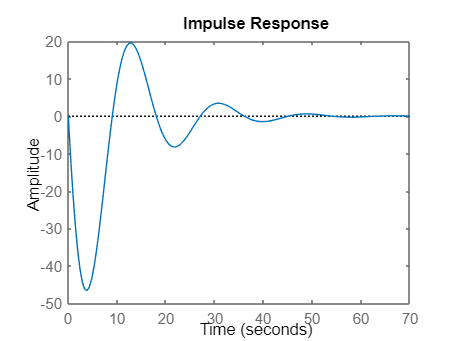

figure (1)
impulse(TFH); %plot the impulse reponse

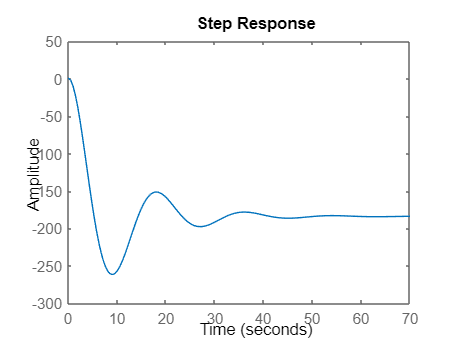

figure(2)
step(TFH) %plot the step response

# 5 Poles

close all
clear all
clc
% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/8/22 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 
% M = 1;                        % TF without motor
%
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

%  
% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback
Hcloop = 1/(1-Hvtheta*Mfb*K)    % use this for motor with feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{a+s}+1\right)}-1}$$

ilaplace(Hcloop)
pretty(simplify(Hcloop))       % to display the total transfer function

% Substitute parameters and solve
% system parameters
g = 9.81;
w_n = 4.88;

l = g/(w_n^2)%22*2.54/100 %effective length
a = 1/0.0459; %nominal motor parameters
b = 0.00323; %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 

% p1 = -1 + 2*pi*i    % dominant pole pair
% p2 = -1 - 2*pi*i    % dominant pole pair 
% p3 = -10
% p4 = -8
% p5 = -8.

p1 = -0.2 + w_n*i   % dominant pole pair
p2 = -0.2 -w_n*i    % dominant pole pair 
p3 = -100
p4 = -42    % dominant pole pair
p5 = -24     % dominant pole pair 

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
% tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)
exp_tgt_char_poly = expand(tgt_char_poly)

% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))
% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)
% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4)


% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)
Ki = double(solutions.Ki)
Ji = double(solutions.Ji)
Jp = double(solutions.Jp)
Ci = double(solutions.Ci)

%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4)

% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

% write out target polynomial 
% bbb = vpa( expand( (s-check_closed_loop_poles(1))*(s-check_closed_loop_poles(2)) ...
%     *(s-check_closed_loop_poles(3))*(s-check_closed_loop_poles(4)) ...
%     *(s-check_closed_loop_poles(5)) ) )



% Plot impulse and step responses of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);
    figure (1)
    impulse(TFH);   %plot the impulse reponse
    figure(2)
    step(TFH)       %plot the step response